% Load images
I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/PreprocessedImages/PrepocessedFinal2.jpg");
I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/P090831011.jpg");
%colorImage = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/PreprocessedImages/PrepocessedFinal2.jpg")

We will use pretrained  (CRAFT) deep learning model and optical character recognition (OCR). CRAFT network will help us to detect the text regions in the input image, threshold region modification and affinity to localise an entire paragraph or a word.

The lowest the affinity Threshold is, the less bounding boxes will identify. And the higher the affinity Threshold is, the amount of boxes increases.

OCR will help to drecognize the characters in the detected text regions.

% Detect each word, we take an input image as the first parameter and we
% apply the affinity threshold to 0.4
bbox = detectTextCRAFT(I,CharacterThreshold=0.4);

% Draw the output bounding boxes in rectangles
Iout = insertShape(I,"rectangle",bbox,LineWidth=5);

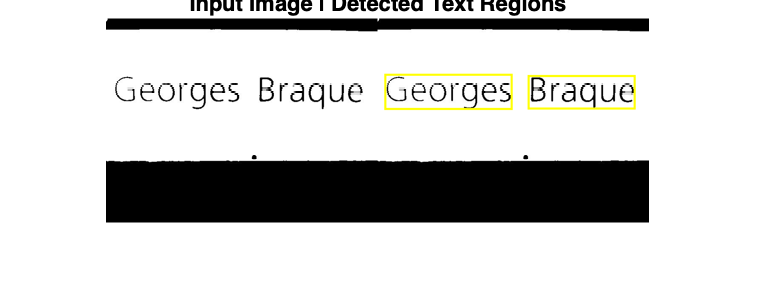

% Display the iamges like a comparison, the left image show us the input
% image and the right image is the detected text regions.
fig = figure(Position=[1 1 700 700]);
ax = gca;
montage({I;Iout},Parent=ax);
title("Input Image | Detected Text Regions")

The next section will consists in the OCR technique application.

% Recognize the text located inside the bounding boxes, this method
% contains information about the recognized text and confidence.
output = ocr(I,bbox);

disp([output.Words])

    {'Georges'}    {'Braque'}

